# 数字图像处理 作业4 (3/25)

阮泉源 201930033629 

## 1 平均去高斯白噪声

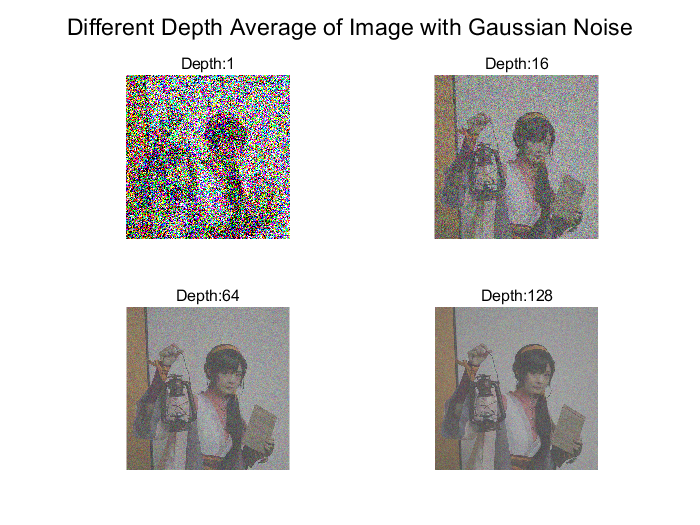

im_coser = imread('coser.jpg');

[w, h, d] = size(im_coser);


depth = [1,16,64,128];

figure;

for N=depth
    
    im_coser_noise = zeros(w, h, d, N);
    
    for i=1:N
        im_coser_noise(:,:,:,i) = imnoise(im_coser, 'gaussian', 0, 1);
    end
    
    im_mean = zeros(w, h, d);
    
    for i=1:N
        im_mean = im_mean + im_coser_noise(:,:,:,i)/N;
    end
    
    im_mean = uint8(im_mean);
    
    subplot(2,2,find(N==depth))
    imshow(im_mean);
    title(['Depth:',num2str(N)])
end
suptitle('Different Depth Average of Image with Gaussian Noise')

结果分析：

    原始图像加上均值为0，方差为1的高斯噪声后，整体画面变得模糊不清，如果能够利用多张叠加了噪声的图片进行均值化处理，能够显著消除噪声，且效果会随着叠加图片的张数的增多而提高。

## 2 均值滤波去高斯白噪声

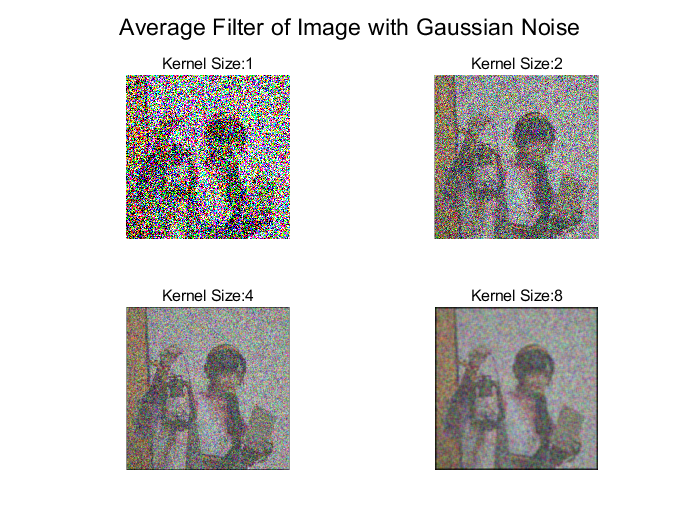

im_coser_noise = imnoise(im_coser, 'gaussian', 0, 1);

kernel_size = [1,2,4,8];

figure;

for N=kernel_size
    kernel = ones(N,N)/(N^2);
    
    im_out = convn(im_coser_noise, kernel);
    
    im_out = uint8(im_out);
    
    subplot(2, 2, find(N==kernel_size));
    imshow(im_out);
    title(['Kernel Size:',num2str(N)]);
end
suptitle('Average Filter of Image with Gaussian Noise')

结果分析：

    采用均值化去高斯白噪声的方法有一定的效果，但效果并不好。在噪声较大时依旧存在着大量的模糊。

## 3 中值滤波去脉冲噪声

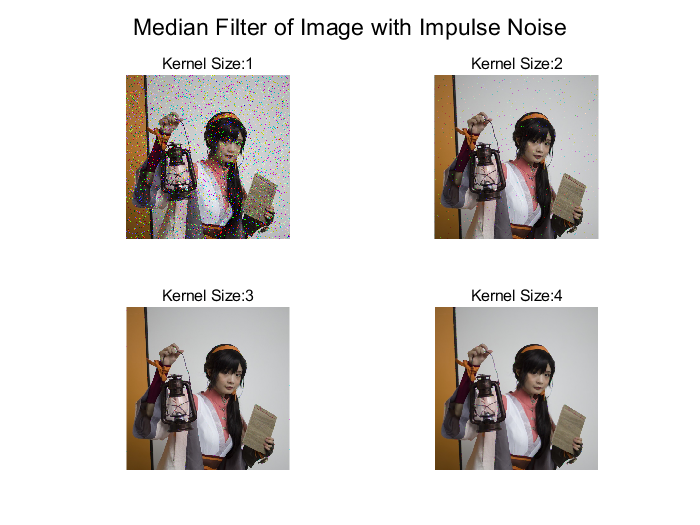

im_coser_noise = imnoise(im_coser, 'salt & pepper');

win_size = [1,2,3,4];

figure;

for N = win_size
    
    im_max = zeros(w+floor(N/2)*2, h+floor(N/2)*2, d);
    im_max(1+floor(N/2):w+floor(N/2), 1+floor(N/2):h+floor(N/2), :) = im_coser_noise;
    
    if N ~= 1
        im_out = zeros(w, h, d);
        for j = 1:w
            for k = 1:h
                im_cut = im_max(j:j+N-1,k:k+N-1,:);
                im_cut = reshape(im_cut,N^2,3);
                im_cut_sort = sort(im_cut);
                if  mod(N^2/2,2) == 0
                    im_out(j,k,:) = [mean([im_cut_sort(floor(N^2/2),1),im_cut_sort(floor(N^2/2)+1,1)]);
                        mean([im_cut_sort(floor(N^2/2),2),im_cut_sort(floor(N^2/2)+1,2)]);
                        mean([im_cut_sort(floor(N^2/2),3),im_cut_sort(floor(N^2/2)+1,3)])];
                else
                    im_out(j,k,:) = [im_cut_sort(floor(N^2/2)+1,1);
                        im_cut_sort(floor(N^2/2)+1,2);
                        im_cut_sort(floor(N^2/2)+1,3)];
                end
            end
        end
    else
        im_out = im_coser_noise;
    end
    subplot(2,2,find(N==win_size));
    im_out = uint8(im_out);
    imshow(im_out);
    title(['Kernel Size:', num2str(N)]);    
end
suptitle('Median Filter of Image with Impulse Noise');

结果分析：

    采用中值滤波的方法处理脉冲噪声（椒盐噪声）非常有效，但随着选择窗口的增大图片会变得模糊不清。

## 4 图像锐化增强

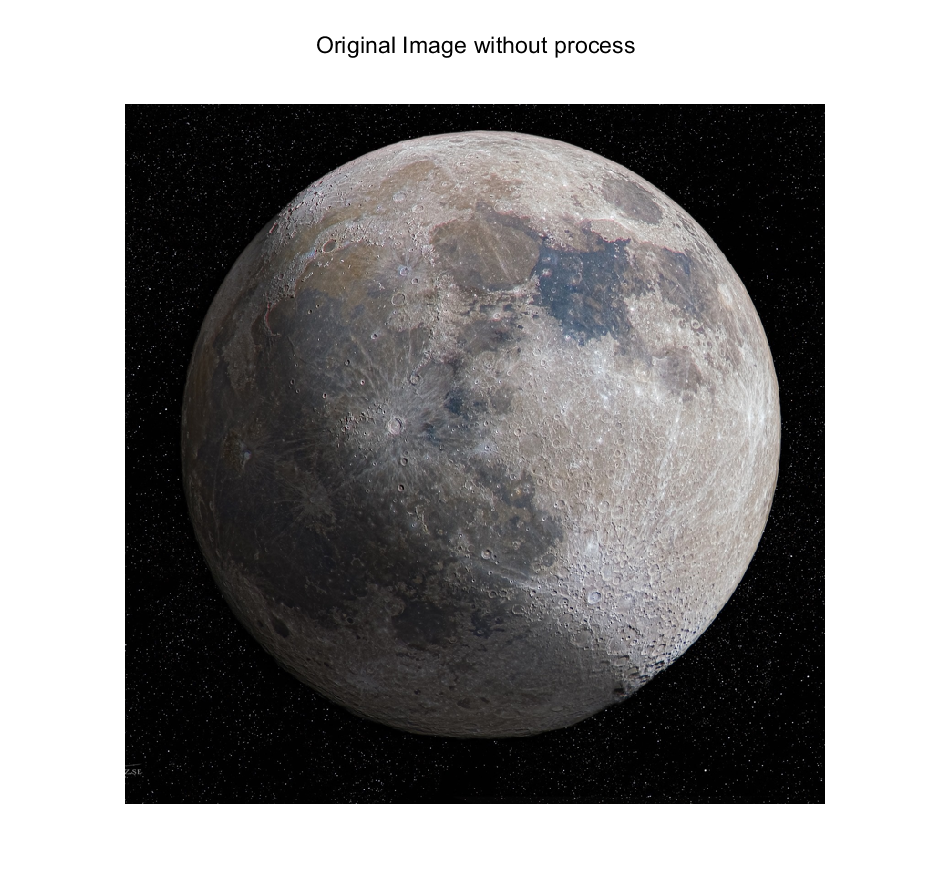

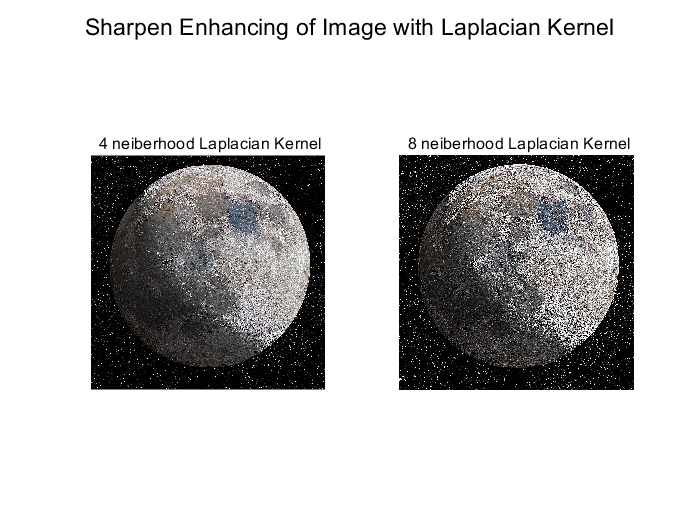

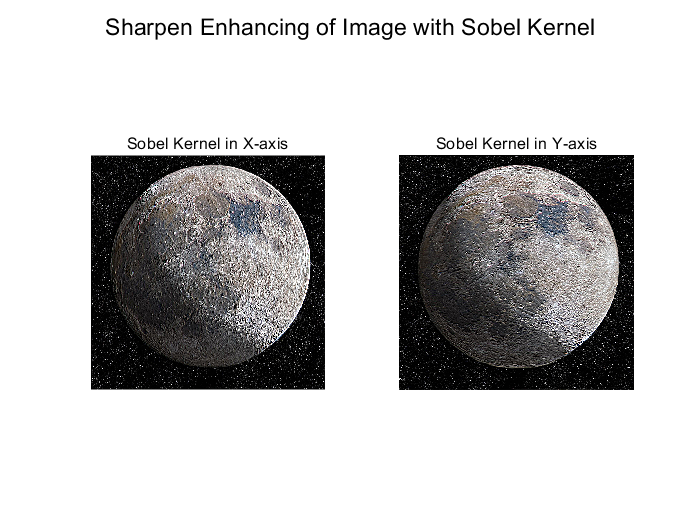

im_moon = imread('moon.jpeg');
im_moon = imresize(im_moon,0.5);

Laplacian_4 = [0, -1, 0; -1, 5 -1; 0, -1, 0];
Laplacian_8 = [-1, -1, -1; -1, 9 -1; -1, -1, -1];

Sobel_x = [-1, 0, 1;-2, 1, 2;-1, 0, 1];
Sobel_y = [-1, -2, -1;0, 1, 0;1, 2, 1];

im_L4 = convn(im_moon,Laplacian_4);
im_L8 = convn(im_moon,Laplacian_8);
im_Sx= convn(im_moon,Sobel_x);
im_Sy = convn(im_moon,Sobel_y);

im_L4 = uint8(im_L4);
im_L8 = uint8(im_L8);
im_Sx = uint8(im_Sx);
im_Sy = uint8(im_Sy);

for i=1:1
    figure;
    imshow(im_moon);
    suptitle('Original Image without process');
    
    figure;
    subplot(1,2,1);
    imshow(im_L4);
    title(' 4 neiberhood Laplacian Kernel')
    
    subplot(1,2,2);
    imshow(im_L8);
    title(' 8 neiberhood Laplacian Kernel')
    
    suptitle('Sharpen Enhancing of Image with Laplacian Kernel')
    
    figure;
    subplot(1,2,1);
    imshow(im_Sx);
    title('Sobel Kernel in X-axis')
    
    subplot(1,2,2);
    imshow(im_Sy);
    title('Sobel Kernel in Y-axis')
    
    suptitle('Sharpen Enhancing of Image with Sobel Kernel')
end

结果分析：

    相较于原始图片，锐化后的图片边缘变得更加明显。

    八邻域拉普拉斯算子的效果比四邻域的效果更好，图片边缘变得更加突出。

    相较于拉普拉斯算子，索贝尔算子的锐化效果更为显著。